## **Principles of Biosignals and Biomedical Imaging**

### **P3, 2nd Semester 2022/2023**

# **Vectors**

## **Lab Session 1**

### **Instituto Superior Técnico**

***100290, Armando Gonçalves***

***100357, Patrícia Marques***

# **1) Synthetic data**

**a) ***x = chirpTone(T, f1, f2, fs)*

***1st Step: ***

function [x] = chirpTone(input1, input2)
 a = input1 + 2;
 output1 = a^2;
 output2 = input2 * 3;
end
T = 1;
fs = 200;
f1 = 0;
f2 = 1;
stepT = 1/fs

stepT = 0.0050

dim = fs*T

dim = 200

time = 0:stepT:T

time =          0    0.0050    0.0100    0.0150    0.0200    0.0250    0.0300    0.0350    0.0400    0.0450    0.0500    0.0550    0.0600    0.0650    0.0700    0.0750    0.0800    0.0850    0.0900    0.0950    0.1000    0.1050    0.1100    0.1150    0.1200    0.1250    0.1300    0.1350    0.1400    0.1450    0.1500    0.1550    0.1600    0.1650    0.1700    0.1750    0.1800    0.1850    0.1900    0.1950    0.2000    0.2050    0.2100    0.2150    0.2200    0.2250    0.2300    0.2350    0.2400    0.2450


x = chirp(time, f1, T, f2)

x =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.9999    0.9999    0.9999    0.9998    0.9998    0.9997    0.9997    0.9996    0.9995    0.9994    0.9993    0.9991    0.9990    0.9988    0.9986    0.9984    0.9981    0.9978    0.9975    0.9972    0.9968    0.9963    0.9959    0.9954    0.9948    0.9942    0.9936    0.9929    0.9921    0.9913    0.9904    0.9895    0.9885    0.9874    0.9862    0.9850    0.9837    0.9823


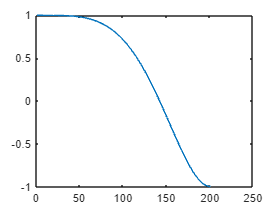

plot(x)

## **b)**

## **c)**

# **2) Real data**

## **a)**

## **b)**

## **c)**

%vetor da dimensão do nr. de frames
signal = zeros(1,video.NumFrames); 

Unable to resolve the name 'video.NumFrames'.

%iteração sobre cada frame
i=1;
while hasFrame(video)
    frame = readFrame(video);
    %média de todos os pixéis do canal vermelho (1)
    signal(i) = mean(frame(:,:,1),'all');
    i=i+1;
end